load("//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/kwave/result/2018_09_08_variousFrequency/statistics.mat",'tof_cell')
load("//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/kwave/param/param_2board.mat")

## 初期設定

t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
[r_num,t_num,model_num,freq_num] = size(tof_cell);
leng = zeros(r_num,t_num);
for i = 1:r_num
    for j = 1:t_num
        leng(i,j) = sqrt((t_pos(1,i)-t_pos(1,j))^2+(t_pos(2,i)-t_pos(2,j))^2);
    end
end

## lt(=v)データの作成

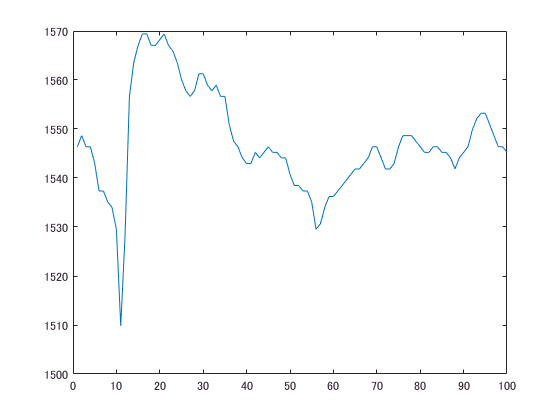

v = zeros(t_num,model_num,freq_num);
for ii = 1:freq_num
    for jj = 1:model_num
        for kk = 1:t_num
            v(kk,jj,ii) = leng(100+kk,kk)/tof_cell(100+kk,kk,jj,ii);
        end
    end
end
figure;
plot(v(:,1,2));

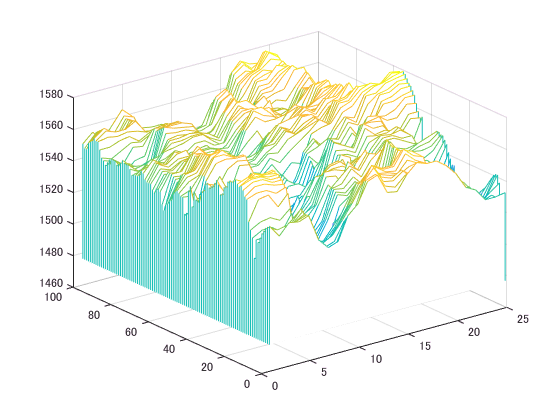

figure;
waterfall(v(:,:,1));

## 参照用のlt(=v)データの作成(下書き)

v_reference = zeros(t_num,model_num);

次に，適切な参照範囲を探す．

displace_t_m = abs(t_pos(1,2) - t_pos(1,1));%[m]
displace_t = displace_t_m / param.grid.dx%[t_num]

displace_t = 4.0404

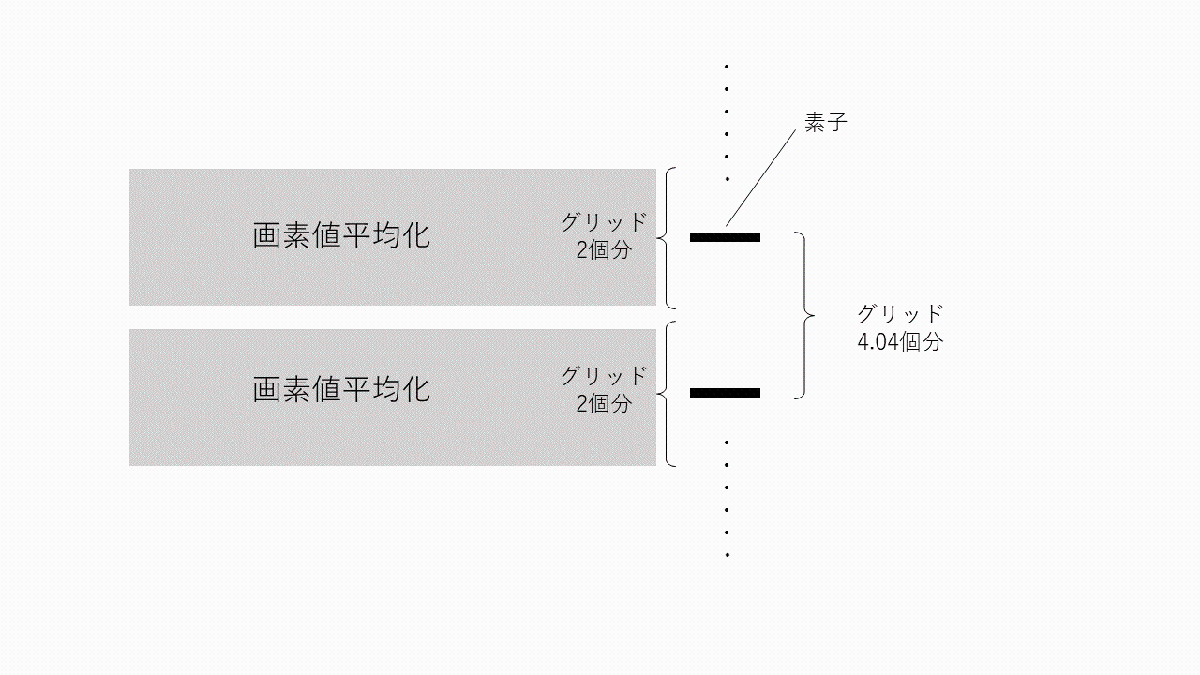

一素子につきグリッド2個分の画素値を平均化して参照用のlt(=v)データの作成を行う．

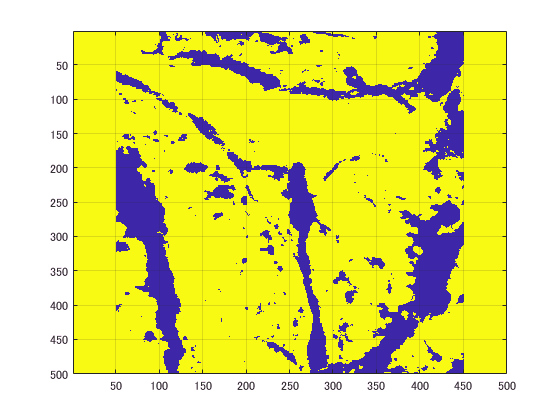

load("//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/kwave/medium/2018_08_10_realisticScatter/case1.mat")
imagesc(medium.sound_speed)
grid on

素子がどのグリッドに位置しているかを求める．

ind_t_pos = zeros(2,200);
[~,ind_t_pos(1,:)] = min(abs(t_pos(1,:)-kgrid.y_vec))

ind_t_pos =     51    55    59    63    67    71    75    79    83    87    91    95    99   104   108   112   116   120   124   128   132   136   140   144   148   152   156   160   164   168   172   176   180   184   188   192   196   200   205   209   213   217   221   225   229   233   237   241   245   249
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


[~,ind_t_pos(2,:)] = min(abs(t_pos(2,:)-kgrid.x_vec))

ind_t_pos =     51    55    59    63    67    71    75    79    83    87    91    95    99   104   108   112   116   120   124   128   132   136   140   144   148   152   156   160   164   168   172   176   180   184   188   192   196   200   205   209   213   217   221   225   229   233   237   241   245   249
   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451   451


下のように画素値を平均することにした．

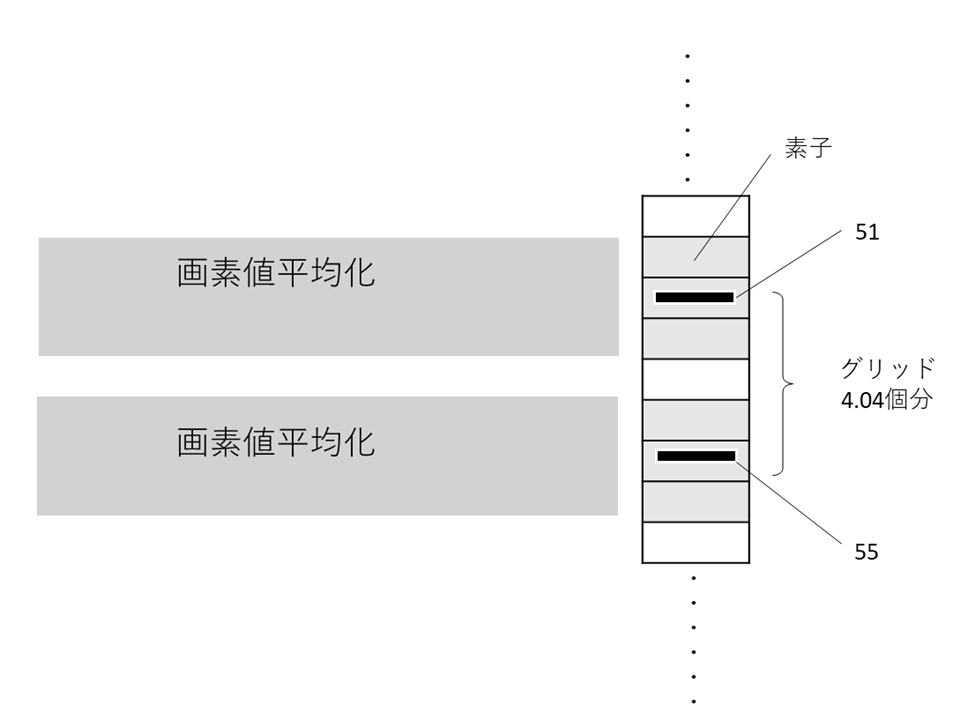

ind_t_pos(:,1)

ans =     51
   451


ind_t_pos(:,101)

ans =     51
    51


参照したグリッドがわかるように，参照したら0をref_medium.sound_speedに埋め込む．

ref_medium = medium;

画素値平均化を行う．

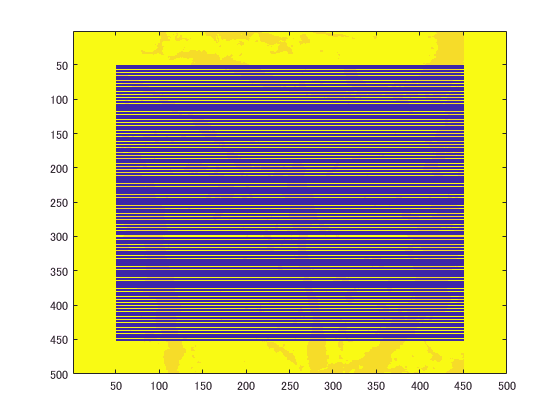

for i = 1:t_num
    v_reference(i,1) = mean2(ref_medium.sound_speed(ind_t_pos(1,i)-1:ind_t_pos(1,i)+1,ind_t_pos(2,100+i):ind_t_pos(2,i)));
    ref_medium.sound_speed(ind_t_pos(1,i)-1:ind_t_pos(1,i)+1,ind_t_pos(2,100+i):ind_t_pos(2,i)) = 0;
end
figure;
imagesc(ref_medium.sound_speed);

準備段階が終了したので，v_referenceの全要素を算出する．

## 参照用のlt(=v)データの作成

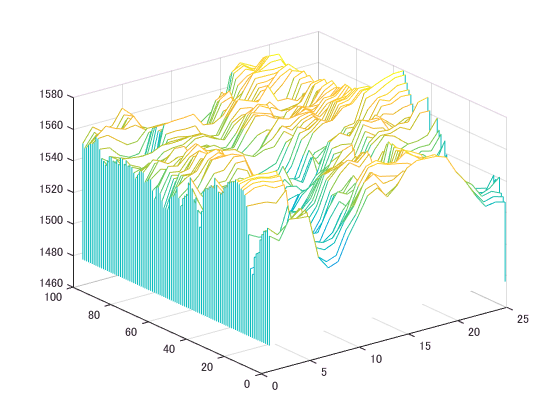

v_reference = zeros(t_num,model_num);

for jj = 1:model_num
    loadfilename = sprintf("//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/kwave/medium/2018_08_10_realisticScatter/case%d.mat",jj);
    load(loadfilename);
    ref_medium = medium;
    for ii = 1:t_num
        v_reference(ii,jj) = mean2(ref_medium.sound_speed(ind_t_pos(1,ii)-1:ind_t_pos(1,ii)+1,ind_t_pos(2,100+ii):ind_t_pos(2,ii)));
    end
end
v_reference = repmat(v_reference,1,1,6);
figure;
waterfall(v_reference(:,:,1));